#  Ladder Development Script

## Overview

I want to add a script to the dendrite class that creates a straight trunk out of one ground node. Each of the branch nodes will connect to the trunk via a perpendicular branch.

Given these points:

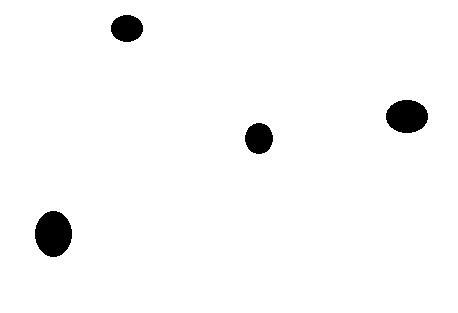

The algorithm should create this network:

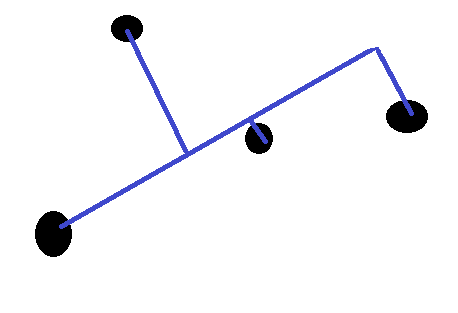

## Setup

Create a simple set of points to start with.

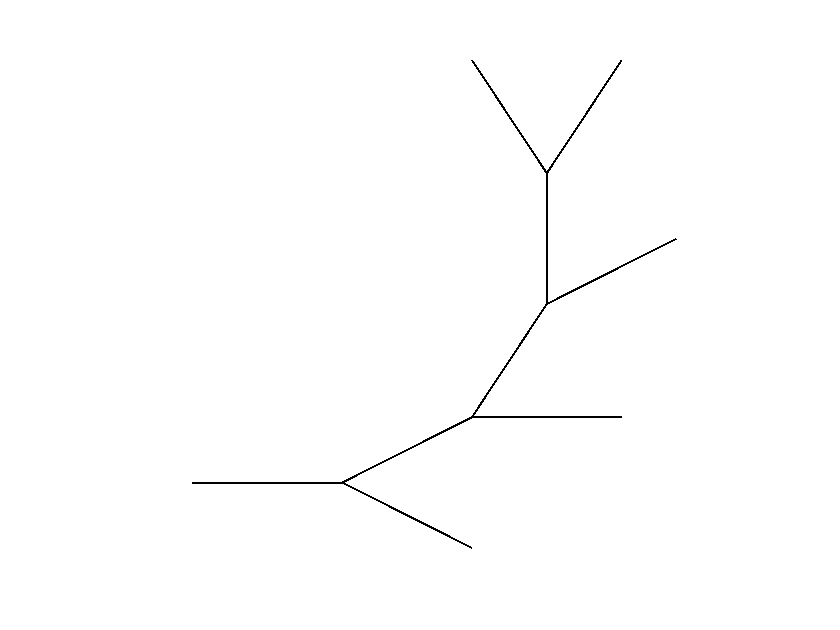

Current plot held


ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


%X = [0; 0.5; 1.5; 2];
%Y = [0; 1; 0.5; 2];
%Z = [0;0;0;0];

d2 = dendrite(trees{20}.dA, trees{20}.X, trees{20}.Y, []);
d2.plot

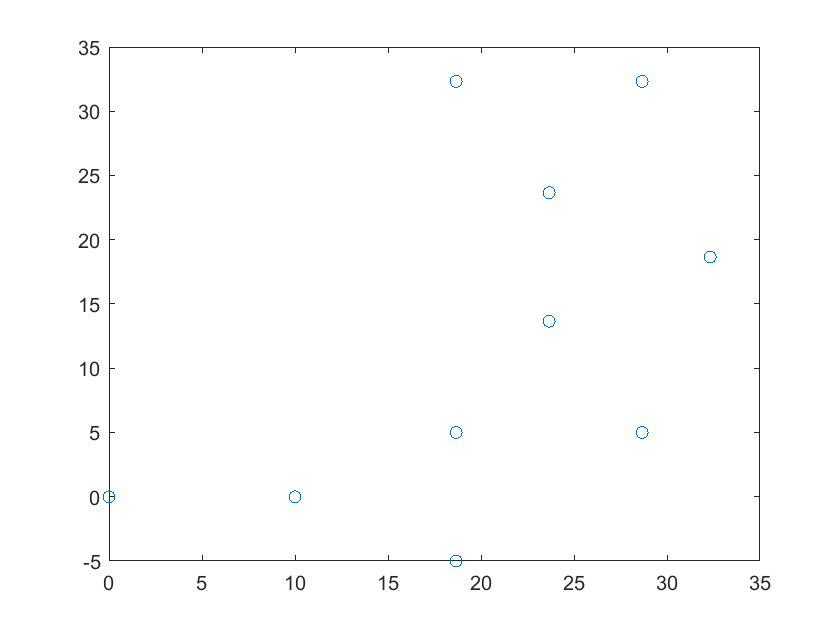


X = d2.X;
Y = d2.Y;
Z = d2.Z;
BCT = d2.BCT;

plot(X,Y,'o','LineStyle','none')



% Use this line to remove all branching points
removeCount = 0;
for i = 1:length(X)
    if(BCT(i)==2)
        X(i-removeCount)=[];
        Y(i-removeCount)=[];
        Z(i-removeCount)=[];
        removeCount = removeCount+1;
    end
end


## Find Trunk Line

The trunk line should go through the GND point and pass as close as possible to as many points as possible. This means that it minimizes the sum of distances from the Trunk to each branch node.

It will sweep a line with an angle from 0 to pi and calcluate the total distance for each case, then find the minimum.

minDist = inf;

minAngle = 0;
GND = [X(1), Y(1), 0];
initialNodes = length(X);
dA = zeros(initialNodes*2-1);

for theta = 0:0.1:pi
    distSum = 0;
    
    linePt = [cos(theta), sin(theta), 0]; % find another point on line
    a = linePt - GND;
    a_norm = norm(a);
    
    for i = 2:length(X)
        pt = [X(i), Y(i), 0];
        b = pt - linePt;
        d = norm(cross(a,b))/a_norm;
        distSum = distSum + d;
    end
    
    if(distSum < minDist)
        minDist = distSum;
        minAngle = theta;
    end
end


plot(X,Y,'o','LineStyle','none')
hold

Current plot held


plot([GND(1), 4*cos(minAngle)], [GND(2), 4*sin(minAngle)])


## Find Branch Points on Trunk

Now that I have the angle of the Trunk, I want to find the point where the trunk branches out to connect with the nodes. Projection will use this formula: (Note that it's important to subtract the GND from each point to make it a vector from the center, then add GND back)

I can ignore the magnitude of a, because I'm just making that a unit vector.

trunkBranchesX = zeros(length(X)-1,1)

trunkBranchesX =      0
     0
     0
     0
     0


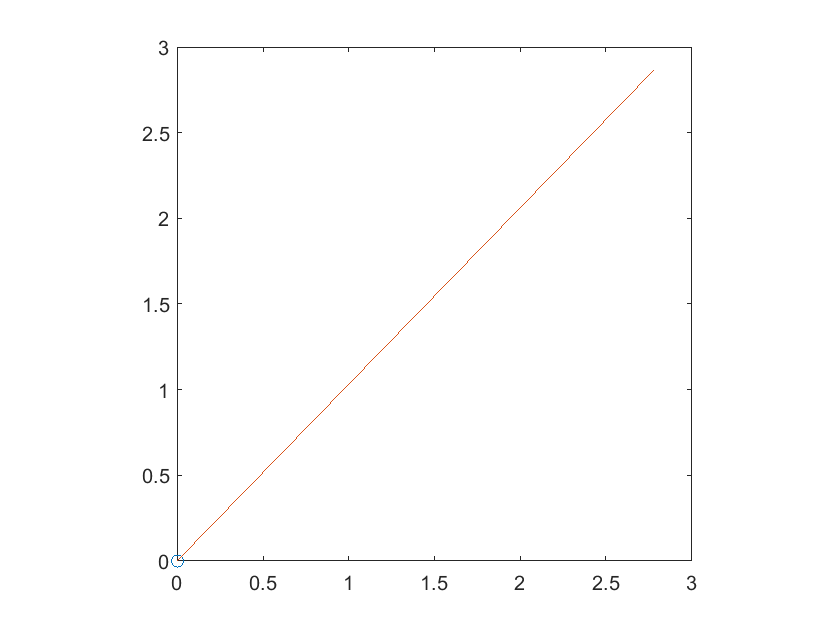

trunkBranchesY = trunkBranchesX;

a = [cos(minAngle), sin(minAngle), 0];

for i = 2:length(X)
    b = [X(i), Y(i), 0] - GND;
    l = dot(a,b);
    trunkPoint = (l*a)+GND;
    trunkBranchesX(i-1) = trunkPoint(1);
    trunkBranchesY(i-1) = trunkPoint(2);
end

plot(trunkBranchesX,trunkBranchesY,'o','LineStyle','none')
axis([0 3 0 3]) 
axis square

%axis([0,3,0,3]);




## Directed Adjacency Matrix

The Directed Adjacency Matrix will indicate that each trunk point connects to its branch node, and to the next trunk point. So I'll start by adding an entry for each of the new branchs to indicate which of the pre-existing node points it connects to.



for i = 1:length(trunkBranchesX)
    dA(i+1, i+initialNodes) = 1;
end



Place all of the Trunk Points in order by their X value. Find the index of each trunk point in this ordering. This step is not necessary if all of the points are already in order, like in this simple example. But this algorithm needs to handle more complex dendrites. 

This currently does not account for dendrites in which the points are all vertically aligned. It is fairly easy to account for this special case, but it's really unnecessary as I don't care about handling that case.

*** I actually did this part wrong. This assumes that the GND point is the leftmost point. This contradicts the entire purpose. I need to include the GND point in the list of Trunk Nodes when I find the index of the points.

[~, ind] = sort(trunkBranchesX);

Now place an entry in the dA connecting each of the trunk points in this order.

dA(find(ind==1)+initialNodes,1) = 1;

for i = 2:length(ind)
    dA(find(ind==i)+initialNodes, find(ind==i-1)+initialNodes)=1;
end



## Dendrite Tests

Now test if the dendrite functions will work on this dA

dLadder = dendrite(dA,[X;trunkBranchesX],[Y;trunkBranchesY],[])

dLadder =   dendrite with properties:

        X: [11×1 double]
        Y: [11×1 double]
        Z: [11×1 double]
       dA: [11×11 double]
      BCT: [1 0 0 0 0 0 1 2 2 2 2]
    nodes: 11


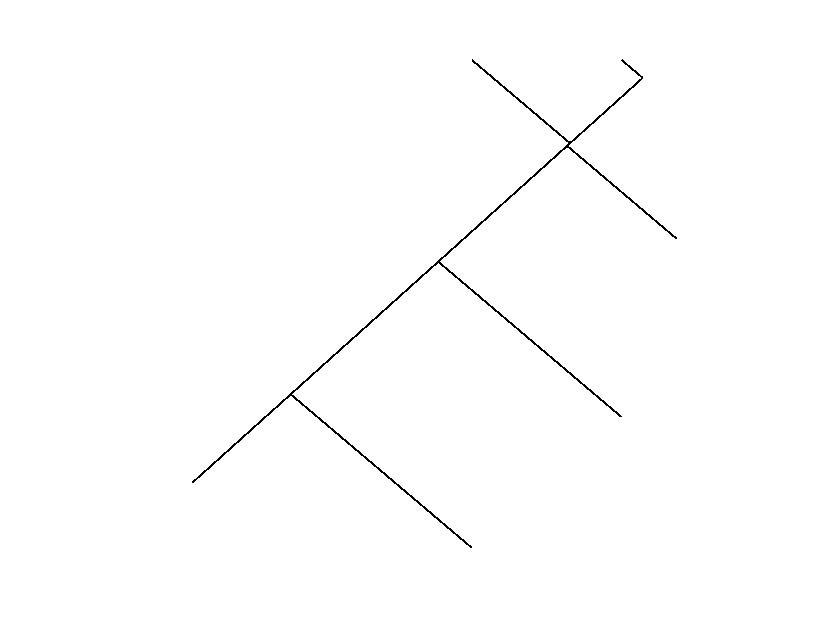

Current plot held


ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


dLadder.plot